# INTRO

This notebook will walk through the analysis of an injured animal in the experiment, from before the injury until a month after the injury was induced.

For this purpose, we will use animal #1 (injured on January 7, 2019).

## Initial view - animal pre injury:

load 2019_01_07_animal_1_L_SigOutput.mat
sig_L = signal_output_mat{1,1};
clear signal_output_mat
load 2019_01_07_animal_1_R_SigOutput.mat
sig_R = signal_output_mat{1,1};
frames = 60000;
fps = 500;
t = 1/fps:1/fps:frames/fps;
tOdd = t(1:2:end-5);

Let's take a look at the signals exported from the animals recording:

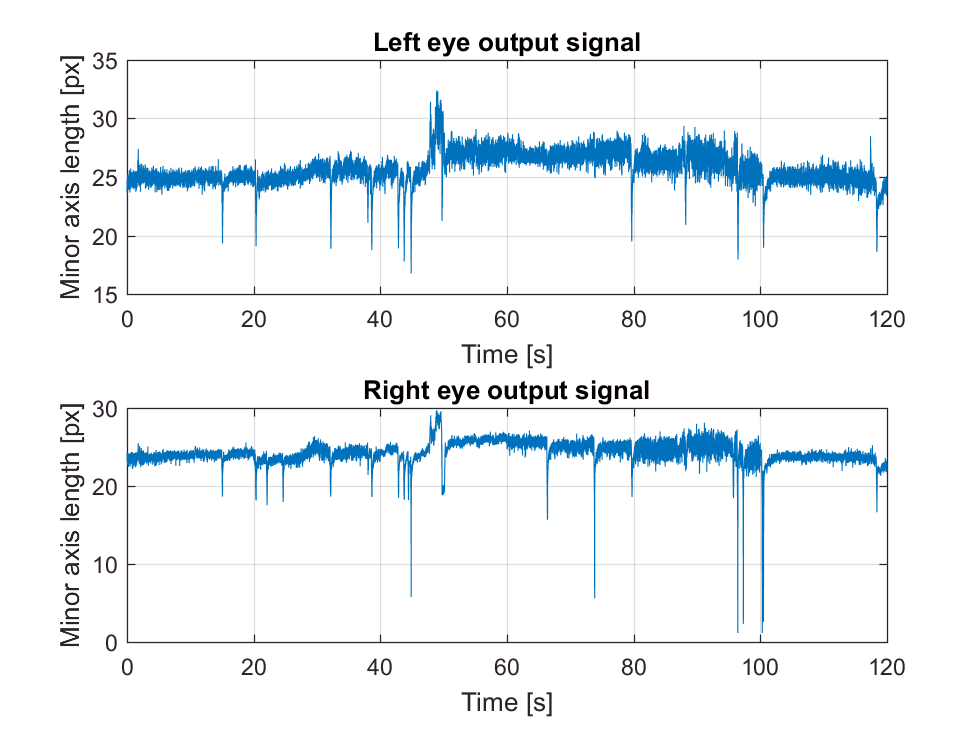

subplot 211
plot(tOdd, sig_L)
title('Left eye output signal');
xlabel('Time [s]'); ylabel('Minor axis length [px]');
grid on;

subplot 212
plot(tOdd, sig_R)
title('Right eye output signal');
xlabel('Time [s]'); ylabel('Minor axis length [px]');
grid on;

As seen in the figure above, the general shape of both signals is roughtly the same; the right eye seems to include a few more small eye closures (negative peaks), which is interesting considering this is prior to the nerve injury, and will make it harder to use blink counts as an indicator for healthy/sick. The right eye is also less noisy than the left eye.

We can inspect the correlation signal between the two:

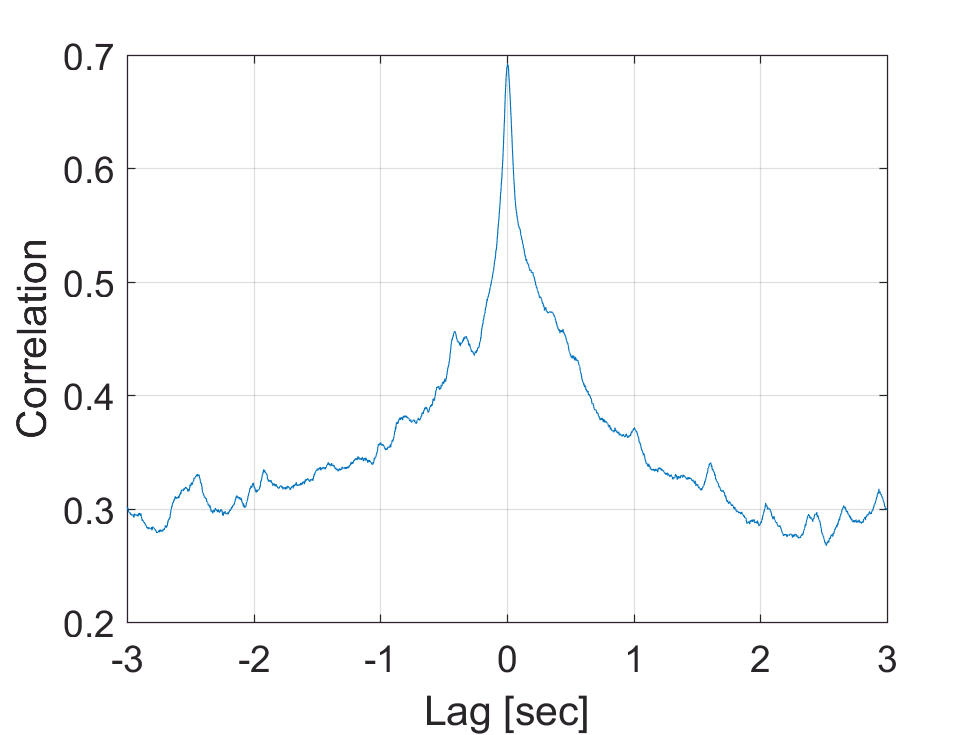

figure()
[correl,lag] = correl_sigs(sig_L,sig_R,fps,1);

As seen above, there definitely is correlation between the two. We will later see how this changes after the animal goes through surgery. Lastly, before continuing to post injury videos, we can look at the spectrum of both eyes (after removing the DC), to insepct any differences or similarities.

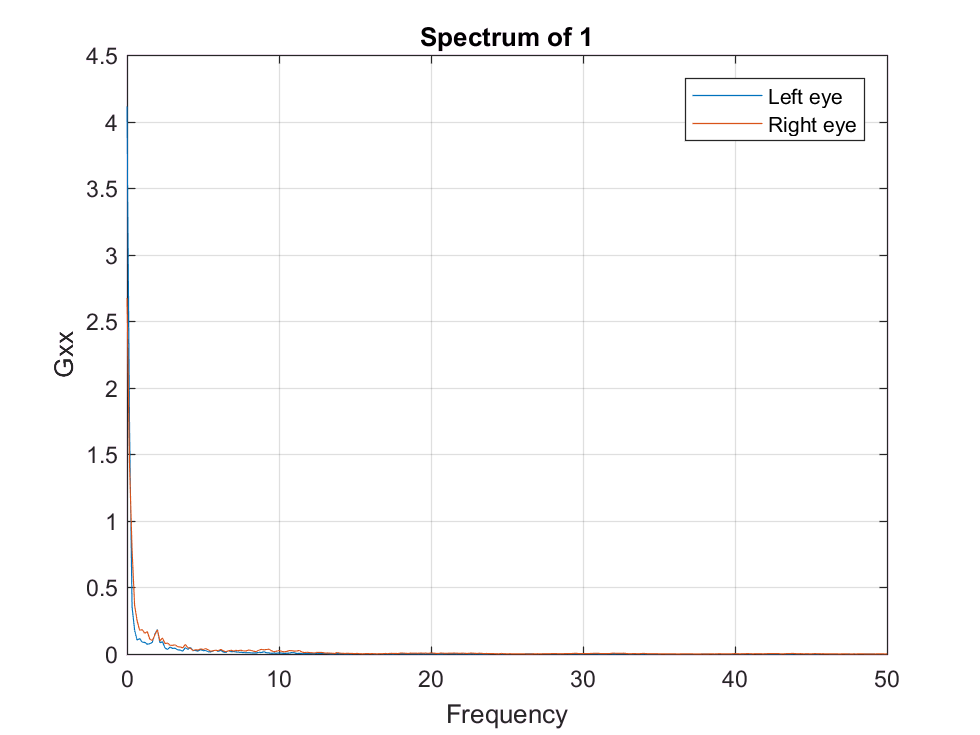

% creating nldats for both sides
left = nldat(sig_L', 'domainIncr',1/fps);
right = nldat(sig_R', 'domainIncr',1/fps);

% extracting spectrum
spec_L = spect(left-mean(left));
spec_R = spect(right-mean(right));
plot(spec_L); 
xlabel('Frequency [Hz]'); ylabel('Spectrum');
grid on;
title('Spectrum');
hold on;
plot(spec_R);
xlim([0 50])
legend('Left eye','Right eye');

## Post Injury Recordings

We can take a look now at what has happened to the animal in the 30 days after going the crush surgery. We'll start off by examining each recording (in pairs, left and right eyes), and eventually look at an overall view.

## Recording 2: January 9th - 2 days post surgery

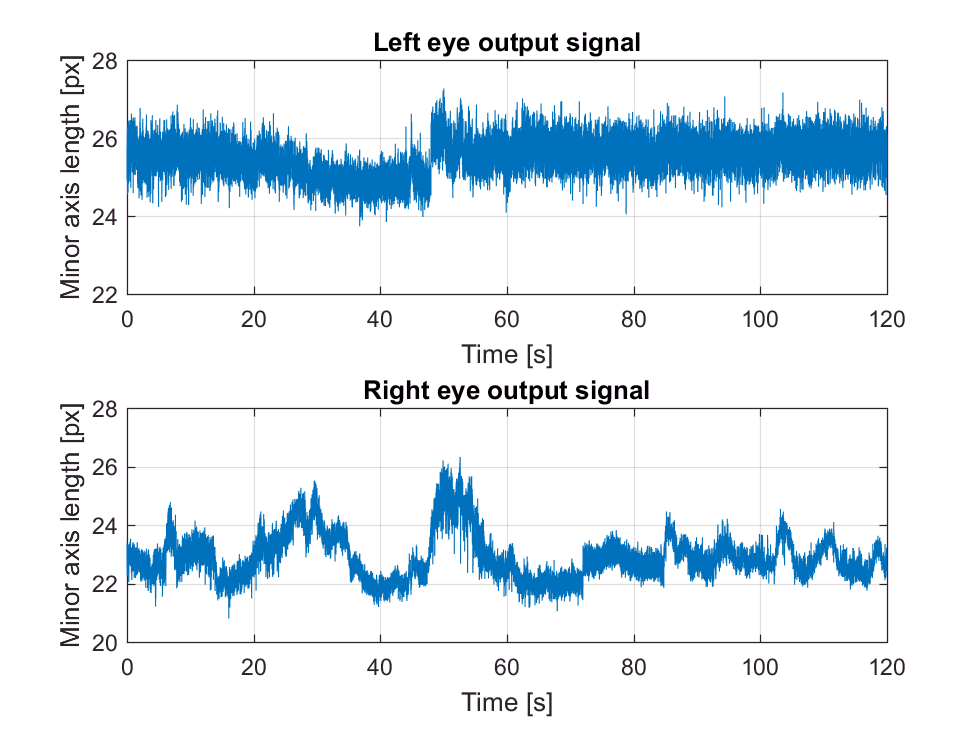

load 2019_01_09_animal_1_L_SigOutput.mat
sig2L = signal_output_mat{1,1};
clear signal_output_mat
load 2019_01_09_animal_1_R_SigOutput.mat
sig2R = signal_output_mat{1,1};
frames = 60000;
fps = 500;
left2 = nldat(sig2L', 'domainIncr',1/fps);
right2 = nldat(sig2R', 'domainIncr',1/fps);

t = 1/fps:1/fps:frames/fps;
tOdd = t(1:2:end-5);

subplot 211
plot(tOdd, sig2L)
title('Left eye output signal');
xlabel('Time [s]'); ylabel('Minor axis length [px]');
grid on;
subplot 212
plot(tOdd, sig2R)
title('Right eye output signal');
xlabel('Time [s]'); ylabel('Minor axis length [px]');
grid on;

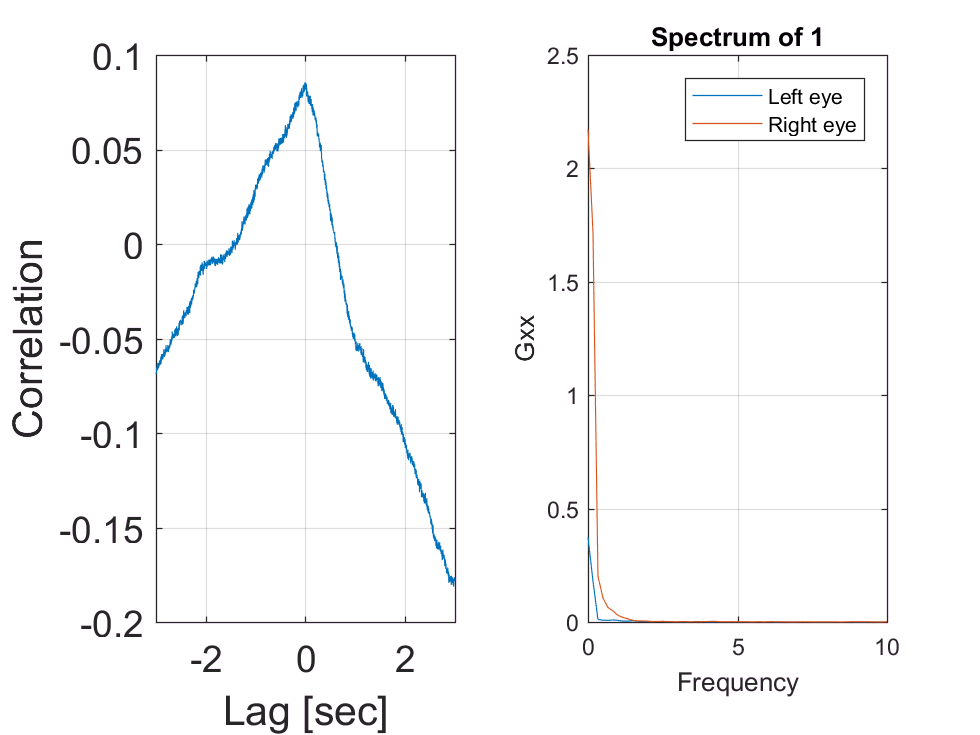


figure()
subplot 121
[correl2,lag2] = correl_sigs(sig2L,sig2R,fps,1);

subplot 122
spec2L = spect(left2-mean(left2));
plot(spec2L); 
xlabel('Frequency [Hz]'); ylabel('Spectrum');
grid on;
title('Spectrum');
hold on;
spec2R = spect(right2-mean(right2));
plot(spec2R);
xlim([0 10])
legend('Left eye','Right eye');

We see a much different situation than before: now, there is virtually no correlation between the two signals, and the left eye signal structure is much less defined, which brings up the assumption that the left eye was the one injured in the surgery.

## Recording 3: January 14th - 7 days post surgery

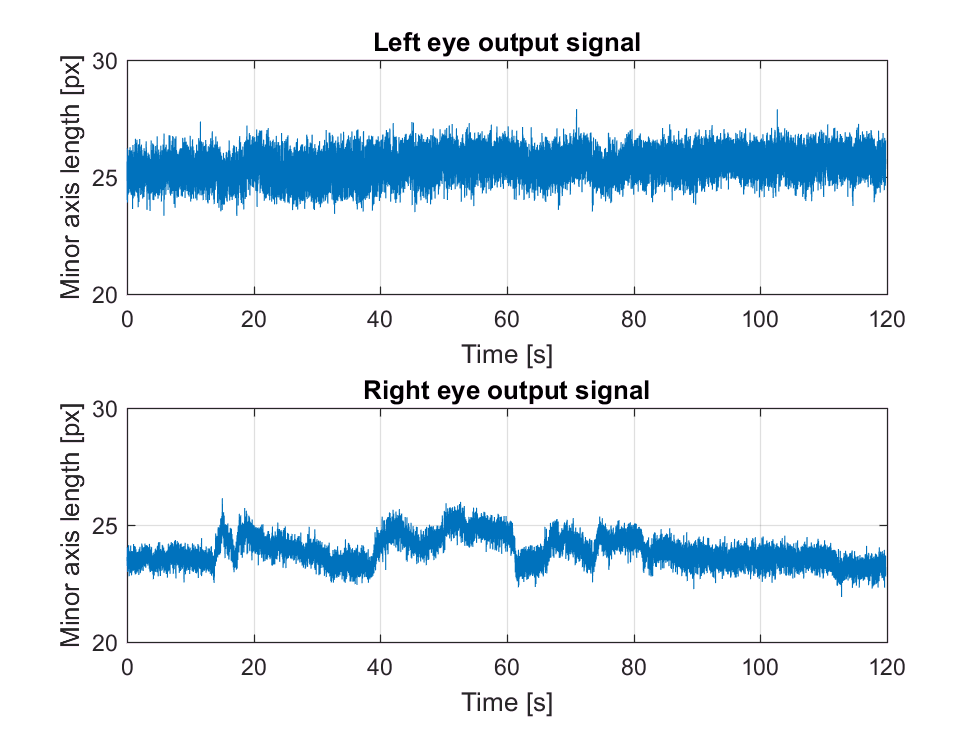

load 2019_01_14_animal_1_L_SigOutput.mat
sig3L = signal_output_mat{1,1};
clear signal_output_mat
load 2019_01_14_animal_1_R_SigOutput.mat
sig3R = [signal_output_mat{1,1}, zeros(1,18)];
sig3L = sig3L(1:end-50);
sig3R = sig3R(1:end-50);

frames = 60000;
fps = 500;
left3 = nldat(sig3L', 'domainIncr',1/fps);
right3 = nldat(sig3R', 'domainIncr',1/fps);

t = 1/fps:1/fps:frames/fps;
tOdd = t(1:2:end-5);
tOdd = tOdd(1:end-50);

subplot 211
plot(tOdd, sig3L)
title('Left eye output signal');
xlabel('Time [s]'); ylabel('Minor axis length [px]');
ylim([20, 30])
grid on;
subplot 212
plot(tOdd, sig3R)
title('Right eye output signal');
xlabel('Time [s]'); ylabel('Minor axis length [px]');
ylim([20, 30])
grid on;

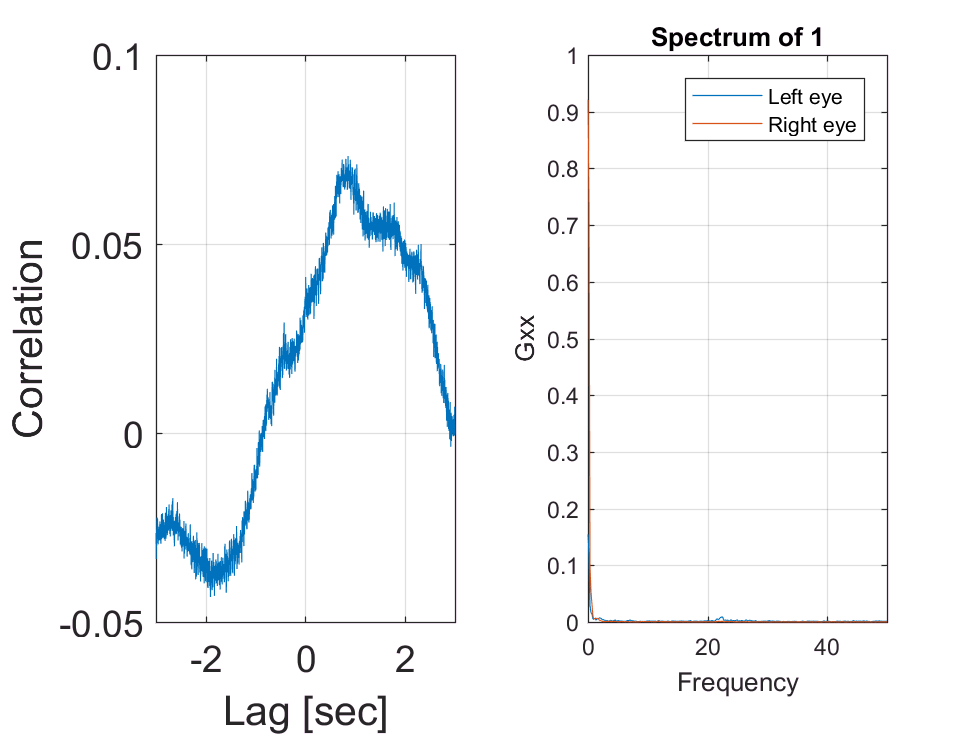


figure()
subplot 121
[correl3,lag3] = correl_sigs(sig3L,sig3R,fps,1);

subplot 122
spec3L = spect(left3-mean(left3));
plot(spec3L); 
xlabel('Frequency [Hz]'); ylabel('Spectrum');
grid on;
title('Spectrum');
hold on;
spec3R = spect(right3-mean(right3));
plot(spec3R);
xlim([0 50])
legend('Left eye','Right eye');

Once again, we see similar behavior to the second recording, as the injury is still prominent.

## Recording 4: January 17th - 10 days post surgery:

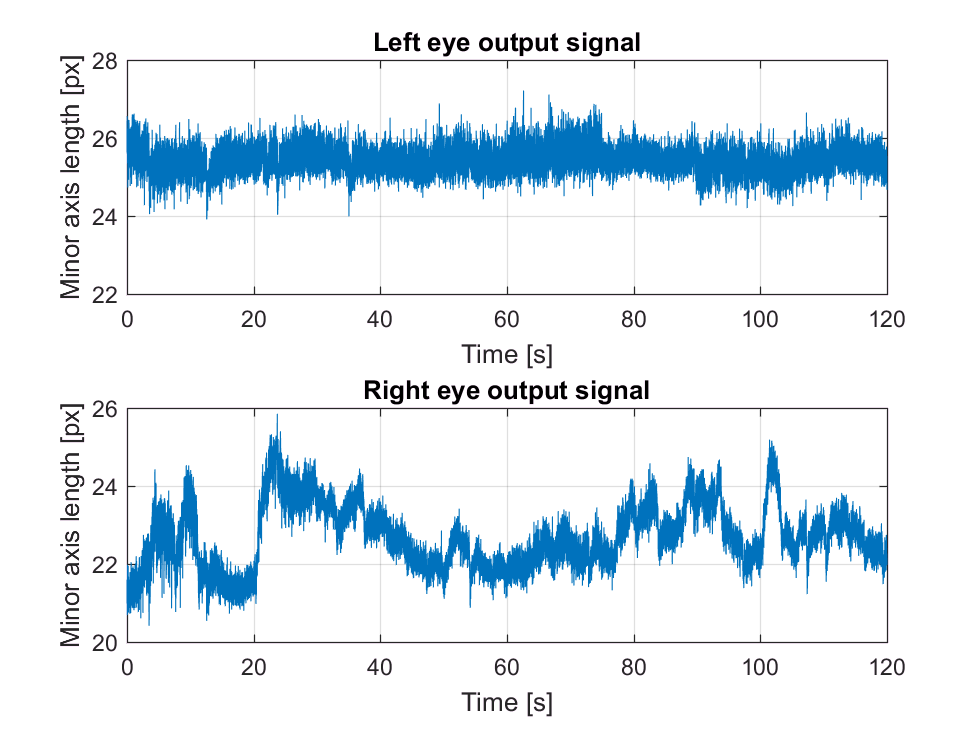

load 2019_01_17_animal_1_L_SigOutput.mat
sig4L = signal_output_mat{1,1};
clear signal_output_mat
load 2019_01_17_animal_1_R_SigOutput.mat
sig4R = signal_output_mat{1,1};
frames = 60000;
fps = 500;
left4 = nldat(sig4L', 'domainIncr',1/fps);
right4 = nldat(sig4R', 'domainIncr',1/fps);

t = 1/fps:1/fps:frames/fps;
tOdd = t(1:2:end-5);

subplot 211
plot(tOdd, sig4L)
title('Left eye output signal');
xlabel('Time [s]'); ylabel('Minor axis length [px]');
grid on;
subplot 212
plot(tOdd, sig4R)
title('Right eye output signal');
xlabel('Time [s]'); ylabel('Minor axis length [px]');
grid on;

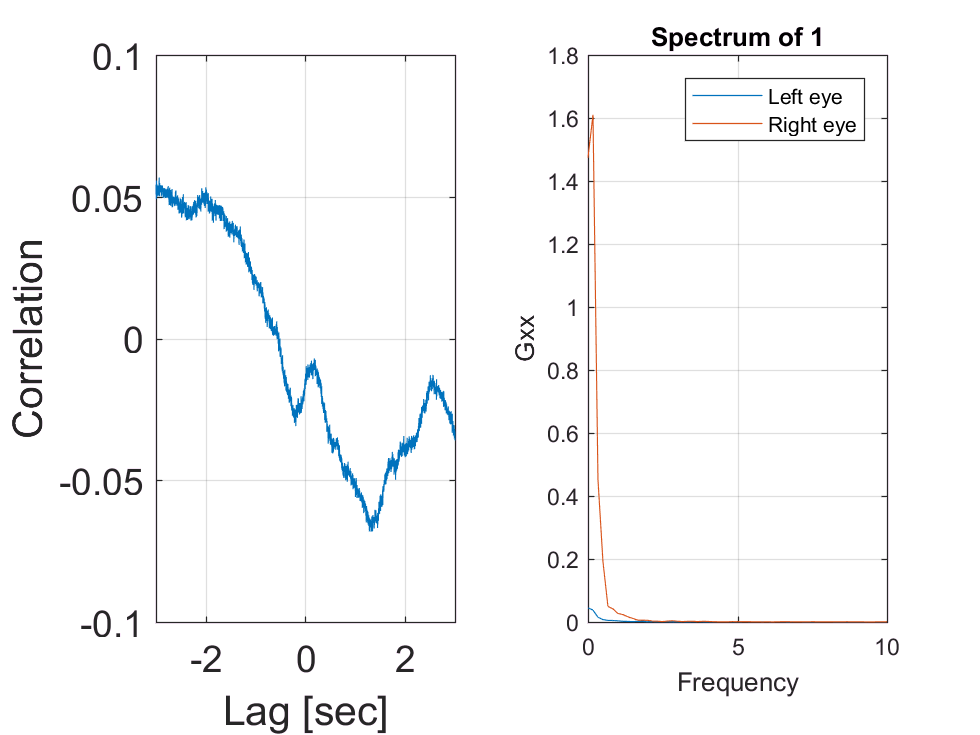


figure()
subplot 121
[correl4,lag4] = correl_sigs(sig4L,sig4R,fps,1);

subplot 122
spec4L = spect(left4-mean(left4));
plot(spec4L); 
xlabel('Frequency [Hz]'); ylabel('Spectrum');
grid on;
title('Spectrum');
hold on;
spec4R = spect(right4-mean(right4));
plot(spec4R);
xlim([0 10])
legend('Left eye','Right eye');

## Recording 5: January 22nd - 15 days post surgery:

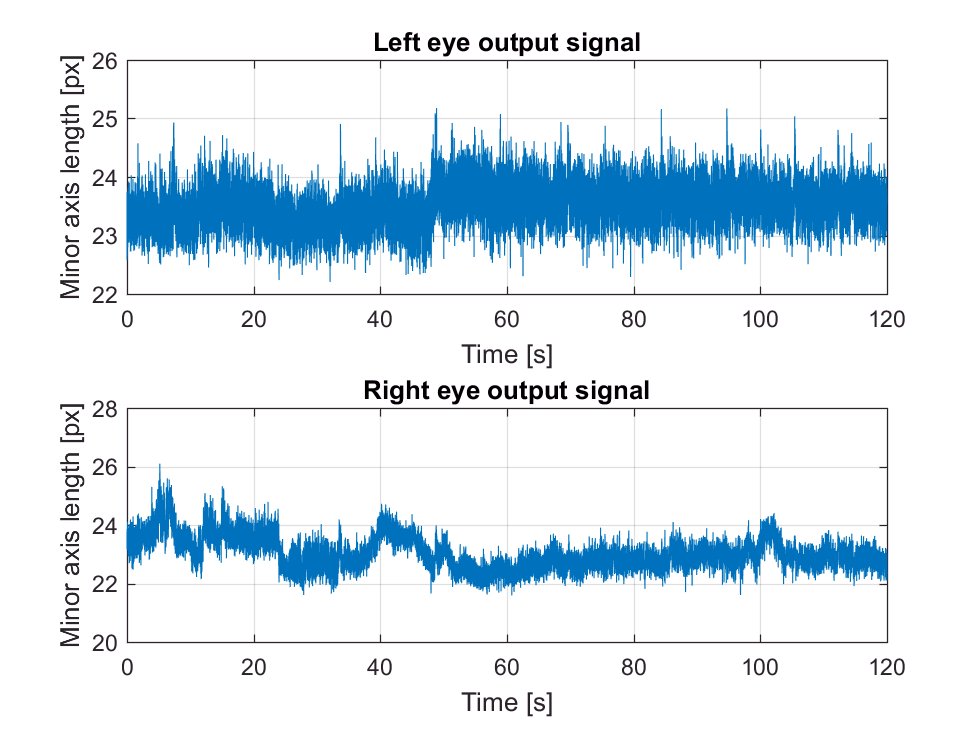

load 2019_01_22_animal_1_L_SigOutput.mat
sig5L = signal_output_mat{1,1};
clear signal_output_mat
load 2019_01_22_animal_1_R_SigOutput.mat
sig5R = signal_output_mat{1,1};
frames = 60000;
fps = 500;
left5 = nldat(sig5L', 'domainIncr',1/fps);
right5 = nldat(sig5R', 'domainIncr',1/fps);

t = 1/fps:1/fps:frames/fps;
tOdd = t(1:2:end-5);

subplot 211
plot(tOdd, sig5L)
title('Left eye output signal');
xlabel('Time [s]'); ylabel('Minor axis length [px]');
grid on;
subplot 212
plot(tOdd, sig5R)
title('Right eye output signal');
xlabel('Time [s]'); ylabel('Minor axis length [px]');
grid on;

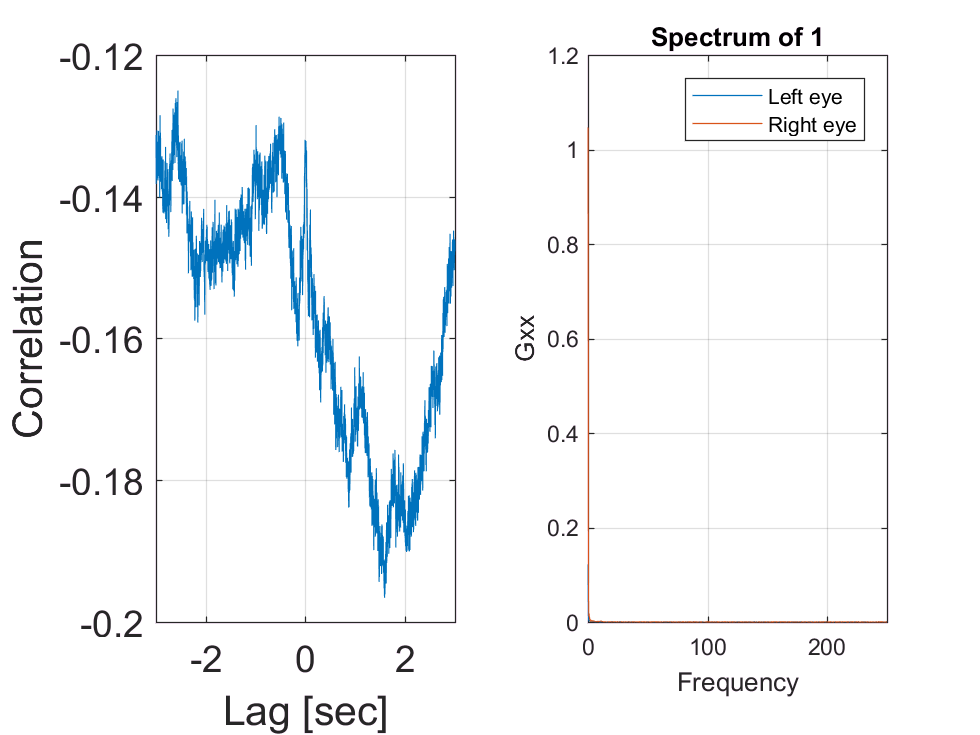


figure()
subplot 121
[correl5,lag5] = correl_sigs(sig5L,sig5R,fps,1);

subplot 122
spec5L = spect(left5-mean(left5));
plot(spec5L); 
xlabel('Frequency [Hz]'); ylabel('Spectrum');
grid on;
title('Spectrum');
hold on;
spec5R = spect(right5-mean(right5));
plot(spec5R);
xlim([0 250])
legend('Left eye','Right eye');

While still highly noisy, we see the left eye signal does get a bit more shape, yet it's very far from the right eye one and does not correlate at all.

## Recording 6: January 28th - 21 days post surgery:

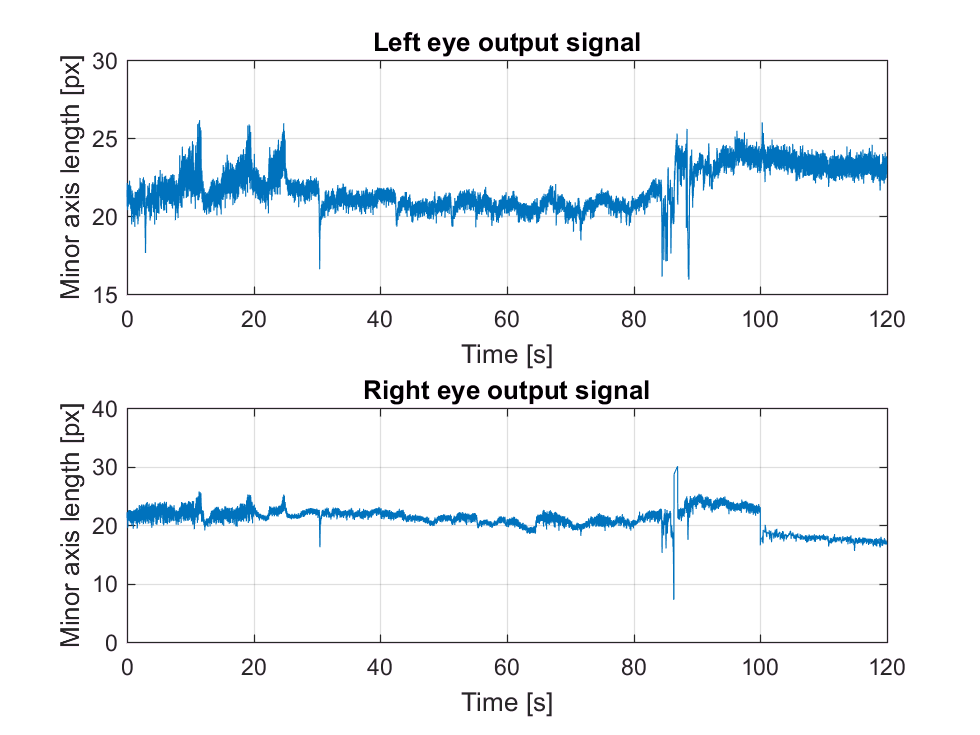

load 2019_01_28_animal_1_L_SigOutput.mat
sig6L = signal_output_mat{1,1};
clear signal_output_mat
load 2019_01_28_animal_1_R_SigOutput.mat
sig6R = signal_output_mat{1,1};
frames = 60000;
fps = 500;

sig6L = sig6L(1:end-10);
sig6R = sig6R(1:end-10);

left6 = nldat(sig6L', 'domainIncr',1/fps);
right6 = nldat(sig6R', 'domainIncr',1/fps);

t = 1/fps:1/fps:frames/fps;
tOdd = t(1:2:end-5);
tOdd = tOdd(1:end-10);

subplot 211
plot(tOdd, sig6L)
title('Left eye output signal');
xlabel('Time [s]'); ylabel('Minor axis length [px]');
grid on;
subplot 212
plot(tOdd, sig6R)
title('Right eye output signal');
xlabel('Time [s]'); ylabel('Minor axis length [px]');
grid on;

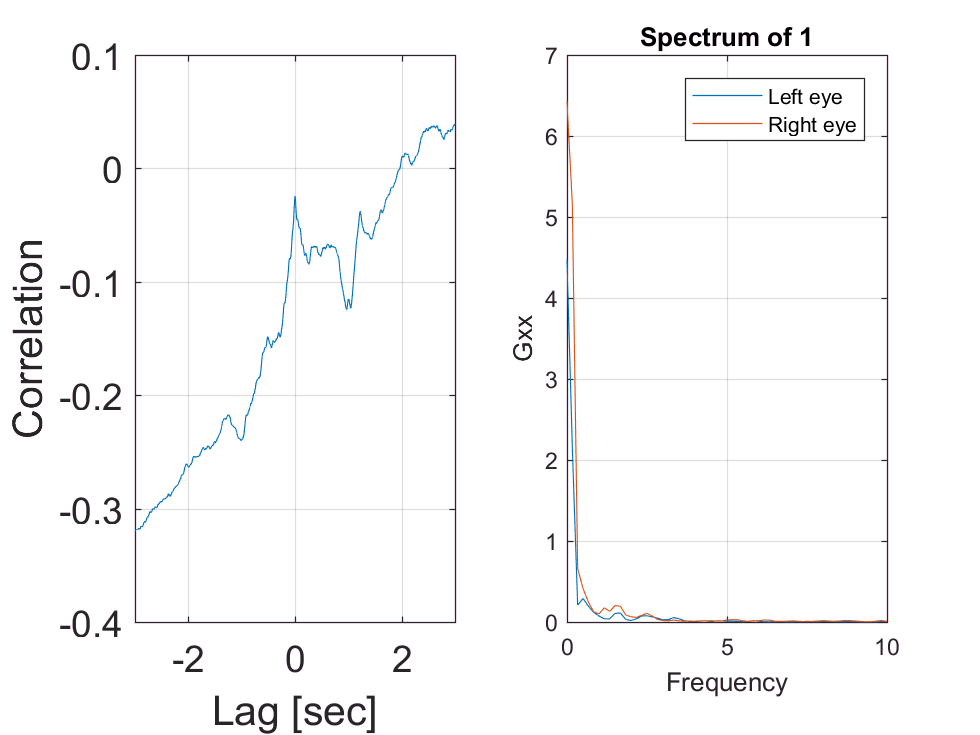


figure()
subplot 121
[correl6,lag6] = correl_sigs(sig6L,sig6R,fps,1);

subplot 122
spec6L = spect(left6-mean(left6));
plot(spec6L); 
xlabel('Frequency [Hz]'); ylabel('Spectrum');
grid on;
title('Spectrum');
hold on;
spec6R = spect(right6-mean(right6));
plot(spec6R);
xlim([0 10])
legend('Left eye','Right eye');

We can see now a significant change compared to previous recordings. Now, while the correlation is still low, we can already see some resemblence between both eyes, with key features in the signal standing out, but the left eye remaining noisier than the right.

Let's look at what happened one month after the surgery.

## Recording 7: February 7th - 30 days post surgery:

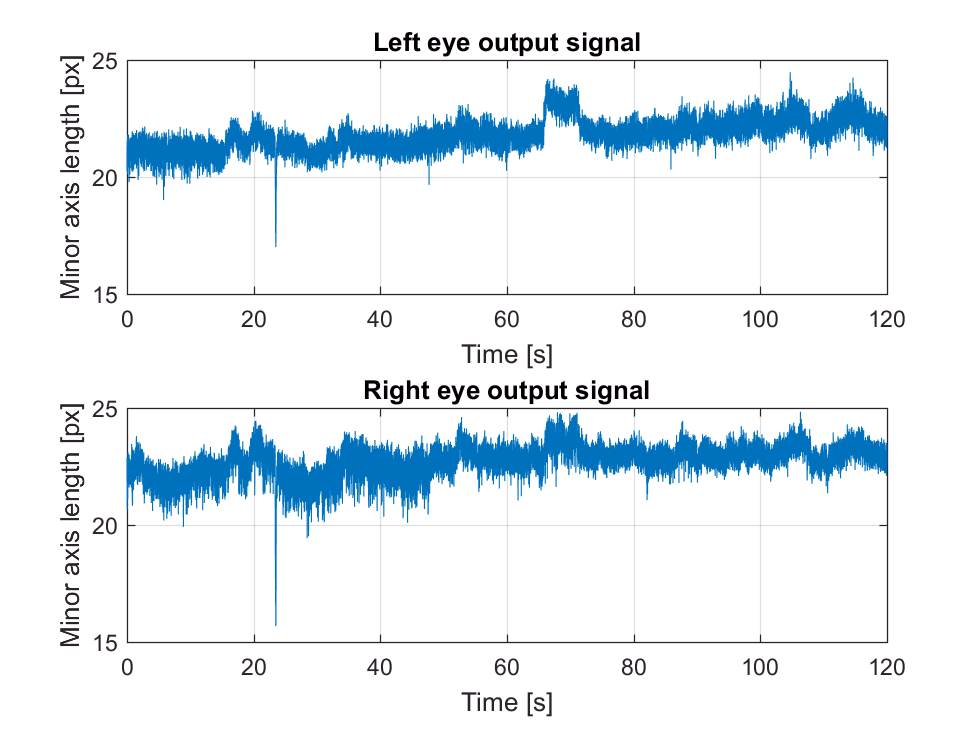

load 2019_02_07_animal_1_L_SigOutput.mat
sig7L = signal_output_mat{1,1};
clear signal_output_mat
load 2019_02_07_animal_1_R_SigOutput.mat
sig7R = signal_output_mat{1,1};
frames = 60000;
fps = 500;

%sig6L = sig6L(1:end-10);
%sig6R = sig6R(1:end-10);

left7 = nldat(sig7L', 'domainIncr',1/fps);
right7 = nldat(sig7R', 'domainIncr',1/fps);

t = 1/fps:1/fps:frames/fps;
tOdd = t(1:2:end-5);
%tOdd = tOdd(1:end-10);

subplot 211
plot(tOdd, sig7L)
title('Left eye output signal');
xlabel('Time [s]'); ylabel('Minor axis length [px]');
grid on;
subplot 212
plot(tOdd, sig7R)
title('Right eye output signal');
xlabel('Time [s]'); ylabel('Minor axis length [px]');
grid on;

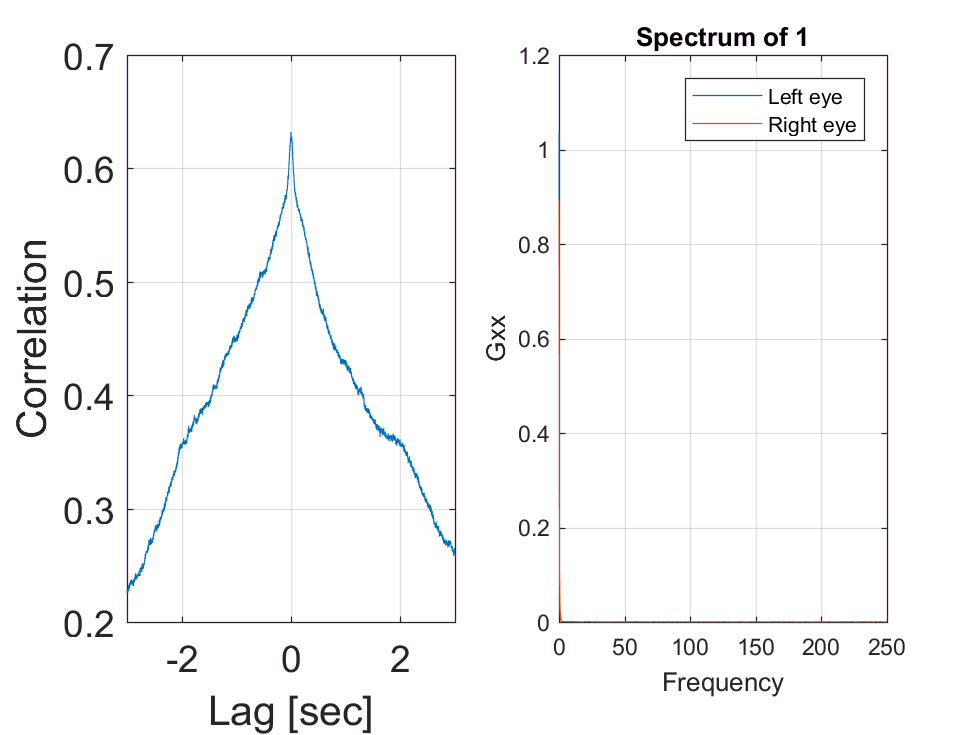


figure()
subplot 121
[correl7,lag7] = correl_sigs(sig7L,sig7R,fps,1);

subplot 122
spec7L = spect(left7-mean(left7));
plot(spec7L); 
xlabel('Frequency [Hz]'); ylabel('Spectrum');
grid on;
title('Spectrum');
hold on;
spec7R = spect(right7-mean(right7));
plot(spec7R);
xlim([0 250])
legend('Left eye','Right eye');

Once again, like before the surgery, we see correlation between the two eyes. Inspecting the two signals themsleves, we see similarity as well, and noise levels in both seem to be similar. 

# Overall Analysis

Things to consider:

- R2 score over time, to show progress

- Blink count over time, to show progress

- Blink count between sides, to detect injury

- Show frequency content in injured high is more disperesed, while healthy eye is lower content

Bink counts can be disregarded as measures for several reasons. First off, not all recordings will contain blinks even in heatlhy rats; second, as seen in recording 1 pre surgery, amount of blinks doesn't indicate health of an eye: different numbers are possible as rat blink isn't symmeterical.

Let's start with inspecting frequency domains, as it holds potential to differ between injured and healthy.

## Frequency Comparisons:

We can look at the healthy spectrums and the injured ones, to see if we spot any key differences. In second stage, we can inspect the distribution of frequency in each case, and compare the two.

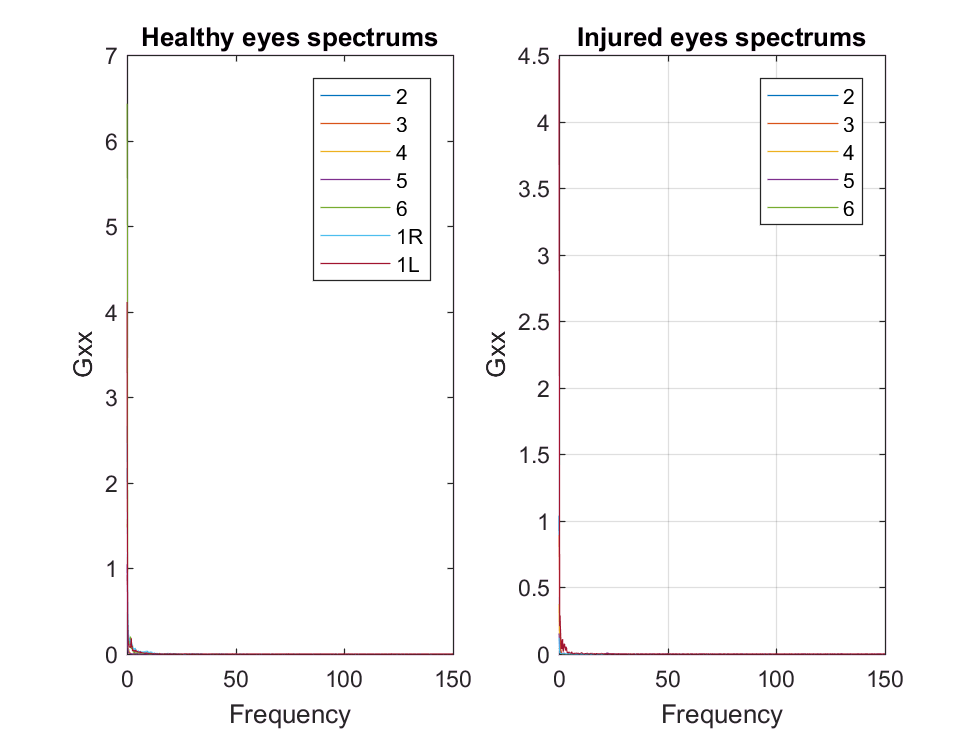

subplot 121
plot(spec2R); hold on;
plot(spec3R); hold on;
plot(spec4R); hold on;
plot(spec5R); hold on;
plot(spec6R); hold on;
plot(spec_R); hold on;
plot(spec_L); hold on;
legend('2','3','4','5','6','1R','1L')

title('Healthy eyes spectrums')
xlim([0 150])
subplot 122
plot(spec2L); hold on;
plot(spec3L); hold on;
plot(spec4L); hold on;
plot(spec5L); hold on;
plot(spec6L); hold on;
legend('2','3','4','5','6')
title('Injured eyes spectrums')
xlim([0 150])

% Getting histograms:

histogram(sig4L, 10000, 'EdgeColor','red'); hold on;

Undefined function or variable 'sig4L'.

histogram(sig4R, 10000, 'EdgeColor', 'cyan'); hold off

An observation from looking at the histograms, is that healthy eyes have a much wider range of values, but the vast majority of them are concentrated in a small portion of it, while injured eyes have a significantly lower range, with values more equally distriibuted.

Let's also extract the correlation coefficient and look what happens to it with time. We can hypothesis that the situation for an animal that's undergoing surgery, will begin with higher correlation, drop, and end at higher value.

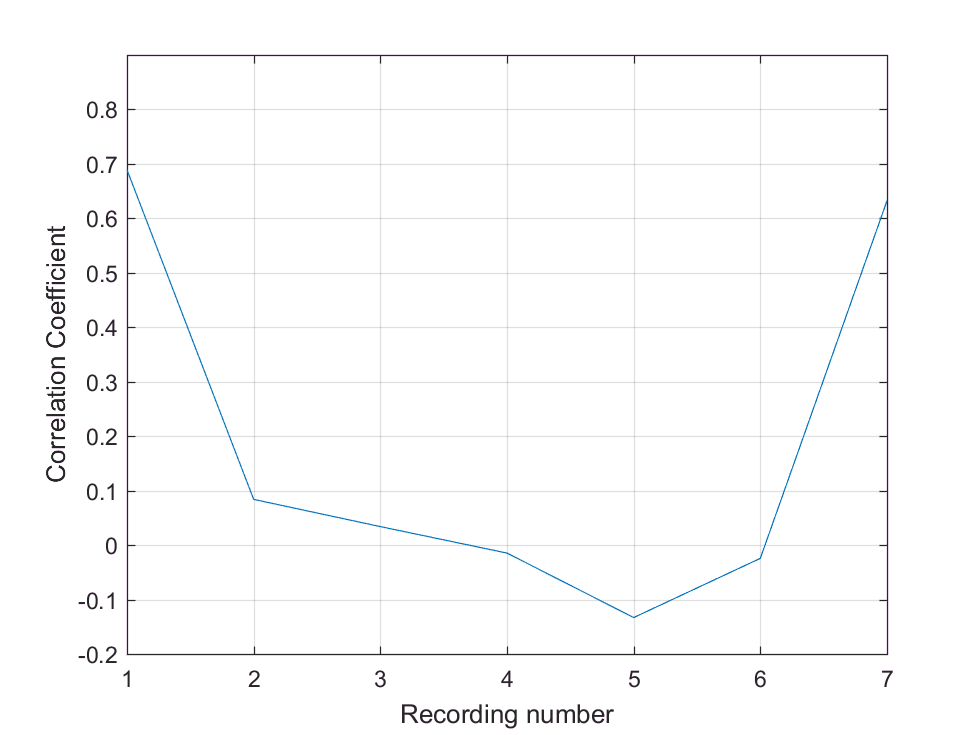

figure
r1 = corrcoef(sig_L,sig_R);
r2 = corrcoef(sig2L,sig2R);
r3 = corrcoef(sig3L,sig3R);
r4 = corrcoef(sig4L,sig4R);
r5 = corrcoef(sig5L,sig5R);
r6 = corrcoef(sig6L,sig6R);
r7 = corrcoef(sig7L,sig7R);
Rs = [r1(1,2), r2(1,2), r3(1,2), r4(1,2), r5(1,2), r6(1,2), r7(1,2)];

plot(Rs)
grid on;
ylim([-0.2 0.9]);
xlabel('Recording number');
ylabel('Correlation Coefficient');

As expected, we see a convex function here. We would expect similar resutls from other animals recordings.